# **Speed and separation monitoring (SSM) algorithm simulation according to ISO/TS 15066**

**This document explains and simulates Speed and Separation Monitoring with a static approach.**

Speed and Separation Monitoring (SSM) [1] [3] [4] allows the robot and the operator to work together in complete safety thanks to a safe distance between the two. Nowadays, there are different systems with sensors on the market, and these systems can be local (sensors are part of the robot itself) or global (sensor is placed on the edge of the table that the robot is mounted on or on the ceiling above the robot’s workspace).

With speed and separation monitoring, the area around the robot is monitored by sensors. At a long distance, the robot will work at high speed, but if someone approaches the robot, this will slow it down and eventually stop if the human is at risk. The main goal is to ensure that the robot stops before contact can be made with the human. One of the main advantages is that the robot is faster and, therefore, much more productive. The robot will only stop if someone enters the workspace, and if the workspace is exited, the robot continues to work at full speed. The robot will thus only stop or slow down when necessary.

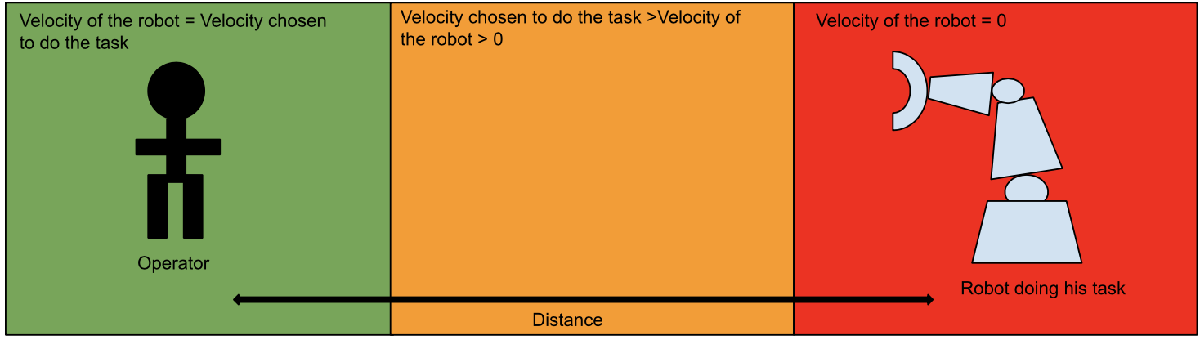

*Image 1 :** Different zones with the 3 different speeds (in green : full speed of the robot ; in yellow : reducing speed of the robot ; in red : Speed of robot = 0 --> Stopping speed) *

The separation distance Sc between the robot and a human body is calculated from ISO/TS 15066 with the following formula [1] [2] [3] [4] [5]: 

    Sc (t0) = Sh + Sr + Ss + C + Zd + Zr

Where : 

-**Sc** (t0) is the minimum protective distance between human and robot at the current time t0.

-**Sh** is the contribution to the protective separation distance attributable to the operator’s

change in location that we can calculate with the following formula :

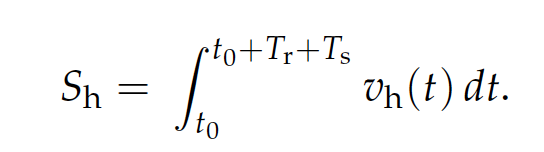

Where:

**    -vh** is the velocity of the operator towards the robot.

**    -Tr** is the time reaction of the robot if he detects a human. It includes times required for the detection of operator position, processing of this signal and activation of the stop command.

**    -Ts** is the time needed for the robot to stop (from the activation of the stop command until the application has stopped, so it means the time when the robot passes from his actual velocity to 0 m/s).

We can calculate a constant value for **Sh** with the following formula: 

**Sh** = vh* (Tr + Ts)

-**Sr** is the contribution to the protective separation distance attributable to the robot system’s reaction time that we can calculate with the following formula :

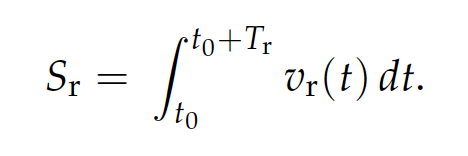

where **vr** is the velocity of the robot in the direction of the operator and **Tr** is the time reaction of the robot when he detects a human. We can calculate a constant value with the following formula: 

**Sr** = vr * Tr

-**Ss** is the contribution to the protective separation distance due to the robot system’s stopping distance that we can calculate with the following formula:

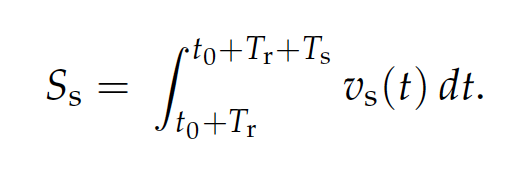

where **vs** is the velocity of the robot in the course of stopping. This velocity is not constant and should decrease linearly once the distance between the robot and the operator is smaller than the minimum protective distance. However, in this case, because we consider the worst case possible, we consider that it is equal to the speed of the robot, and so it is constant.

-**C** is the intrusion distance (defined in ISO 13855). This is the distance that a part of

the body can intrude into the sensing field before it is detected. (For example, the norm assumes that 1.6 m/s is the speed of a human body. In the case of the sensor CH101 by TDK, we have 100 samples per second. That means that the intrusion distance is 16mm [6]) 

-**Zd** is the position uncertainty of the operator in the collaborative workspace (the order of magnitude should be in mm), as measured by the presence sensing device resulting from the sensing system measurement tolerance. It can be defined, thanks to the datasheet of the chosen sensor, by looking at its level of precision (the sensor will have some error on the measurement depending on the distance where the obstacle is --> look at the noise generated by your sensor). It is also possible to determine this value by doing experiments with the chosen sensor.

-**Zr** is the position uncertainty of the robot system (the order of magnitude should be in mm), resulting from the accuracy of the robot position measurement system. It can be defined, thanks to the datasheet of the chosen robot, by looking at its level of precision. It is also possible to determine this value by experimenting with the robot.

***The result of the algorithm is the following :***

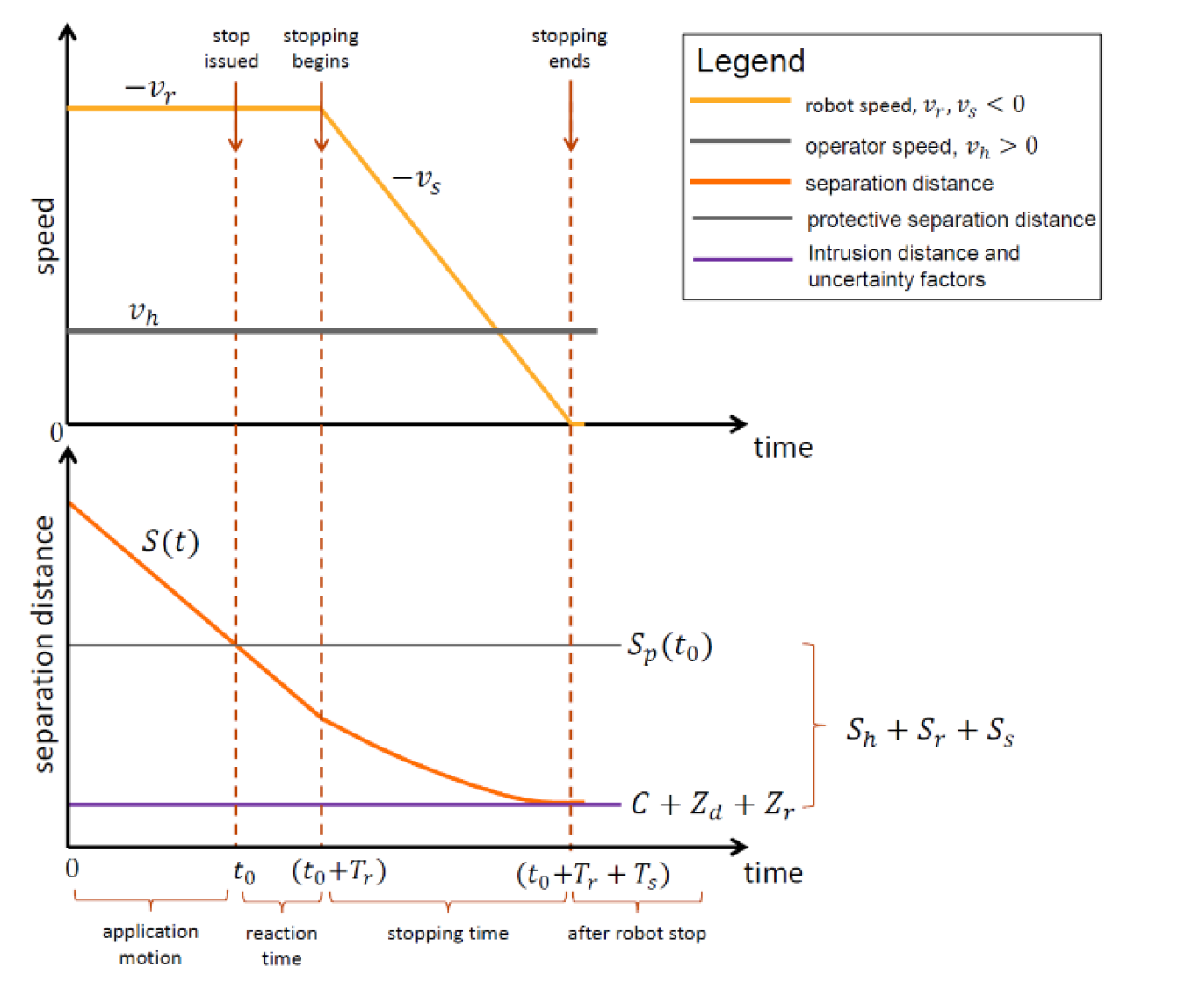

*Image 2 :** Speed of the robot depends on the distance between the robot and the operator, based on speed and monitoring separation [3]*

*-Graph of ****speed depending on time ****in Image 2 :* The robot has a constant speed **vr** until the minimum protective distance **Sp(t0)** has been exceeded. The robot takes some time to change his velocity, which depends on its reaction time **Tr**. The speed of the operator **vh** meanwhile remains constant and has a direction opposite to the robot. In the case considered, the operator approaches the robot at a constant speed.

*-Graph of ****separation distance depending on time**** in Image 2 :*  While the robot is doing its task at a certain speed, an operator approaches until reaching the minimum protective distance. The operator approaches the robot step by step until the minimum protective distance is reached. Once this distance is reached, the robot takes a certain time to react before starting to decrease in speed. The more the distance between the robot and the operator decreases, the more the speed decreases until reaching the distance where the robot must reach a speed of 0.

It must also be taken into account that the speeds vr and vs are linked to the robot and have a different sign at **vh** (because they have an opposite direction) that is related to the operator.

To resume : 

-**Input** : distance between robot and the operator given by the sensors.

-**Output** : velocity of the robot.

## Simulation of the algorithm

In order to be able to simulate this algorithm, we can consider the following method :

Considering that all the velocities are constant: A first approximation is to consider the speed of the robot and the operator as constant. We thus consider that we receive separation distance between the robot link and the human body who are closest. We have to consider the worst case, that means the maximum velocity and time reaction to have better security.

The first thing to do is to define each variable in order to calculate the minimum protective distance **Sc**. Put the value depending on the robot and the sensor that you use and the task that you execute :


% Speed and separation monitoring algorithm - Method considering all
% velocities and time constant
clear ;
close all;
clc;


%Variable to determine 

%Here, we consider a UR10 robot (where the datasheet is available on
%Universal Robot website [6]). We also consider for the sensor the CH101
%(Ultrasonic sensor [7]). Find the different datasheet to
%find the following values or do experiments.


%Reaction time of the robot [s] (considered constant and can be
%determined by experiments or with datasheet of the robot you consider)
%It is the time needed when the robot starts to slow down when the minimum
%protective distance has been reached.
T_reaction =0.024;

%Stopping time of the robot (time to reach from the initial velocity of robot
%to 0) [s]. Considered constant and can be determined by experiments or
%with datasheet of robot. The stopping time also depends on the initial
%velocity but you can consider the maximum value of the velocity of your
%robot to determine the time needed for the robot to reach a velocity of 0.
T_stopping =0.75 ;

%Velocity of an operator to the robot in the collaborative workspace
%[m/s] (considered constant. We can consider the maximum speed of a walking
%human being around 2 m/s [3].
v_human =1.6 ;

%Velocity of the robot in the direction of the operator [m/s]
%(considered constant)
%Put the velocity imposed to the robot to achieved his task. This velocity
%can be choose in ROS, where you can choose the velocity of your
%end-effector [m/s] or the velocity of the different rotational joints
%[rad/s]. Make differential kinematics to pass from one velocity to
%another.
v_robot =1.5 ;

%Velocity of the robot in the course of stopping [m/s]
%(varies linearly once the minimum protective distance has been reached)but
%in this case, we consider it constant and with his maximum value
v_stopping = v_robot; 


%Velocity of the robot when entering in the intrusion distance with
%uncertainty (the distance when the robot has to stop because the operator
%is too close)
V_Stop = 0;


%Create a vector with the different values of the distance and velocity to create a plot
Velocity = [];
Distance = [];
i=1; 

%Distance between the operator and the robot (that changes over time
%because the operator approaches the robot)
%Variable in the real life that gives the different sensors on the robot
%We want to simulate this distance on Matlab
Total_Distance = 4.5;  



%We calculate/determine each term of the minimum protective distance
%We suppose that each velocity and time reaction is constant


Sh = v_human * (T_reaction + T_stopping); % Function in the case that the velocity is constant 
Sr = v_robot * T_reaction; % Function in the case that the velocity is constant  
Ss = v_stopping* T_stopping;   % The velocity will change if we reach the minimum protective distance


%Constant to be determined considering the robot that we use and the
%sensors to determine the distance 
C =0.016 ; %Intrusion distance, as defined in ISO 13855 (distance that is part of the body can intrude into the sensing field before it is detected)
Zd =0.001 ; %Position uncertainty of the operator in the collaborative workspace (depending of the tolerance of the sensing system measurement)
Zr =0.001; %Position uncertainty of the robot system (depending of the accuracy of the robot position measurement system)
    
    
%Distance to stop the robot (velocity is zero)
D_Stop = C + Zd + Zr;

%Protective separation distance (also constant)
Sc = Sh + Sr + Ss + C + Zd +Zr; 
    

We simulate the algorithm during 15 seconds, changing the distance between the robot and the operator and we calculate each time the actual velocity of the robot meanwhile an operator is approaching the robot.

for t = 0:0.1:15

   
    %The distance between the robot and the operator is less than the minimum protective separation distance
    if Total_Distance <= Sc   
        v_stopping = (Total_Distance - D_Stop)/(Sc-D_Stop) * v_robot;

        %To avoid negative velocity of the robot
        if v_stopping < 0    
           v_stopping = 0;
        end
        Velocity(i) = v_stopping;


    %The distance between the robot and the operator is more than the minimum protective separation distance
    elseif  Total_Distance > Sc
        v_stopping = v_robot;
        Velocity(i) = v_robot;

    %The distance between the robot and the operator is less than the distance when the robot has to stop
    elseif Total_Distance <= D_Stop   
        v_stopping = 0;
        Velocity(i) = v_stopping;
    end
    

**We must also simulate the trajectory of the operator, which will be done in several steps:  **

- **The operator will first approach a first time (2s)**

- **Stop for a certain time (2s)**

- **Approach a second time (4s)**

- **Stop in front of the robot (2s)**

- **Finally move away (1s)**

- ** Stop again (2s)**

- **Move away again (2s) **

The assumption is that we consider a vertical approach with only one sensor on the robot's base.

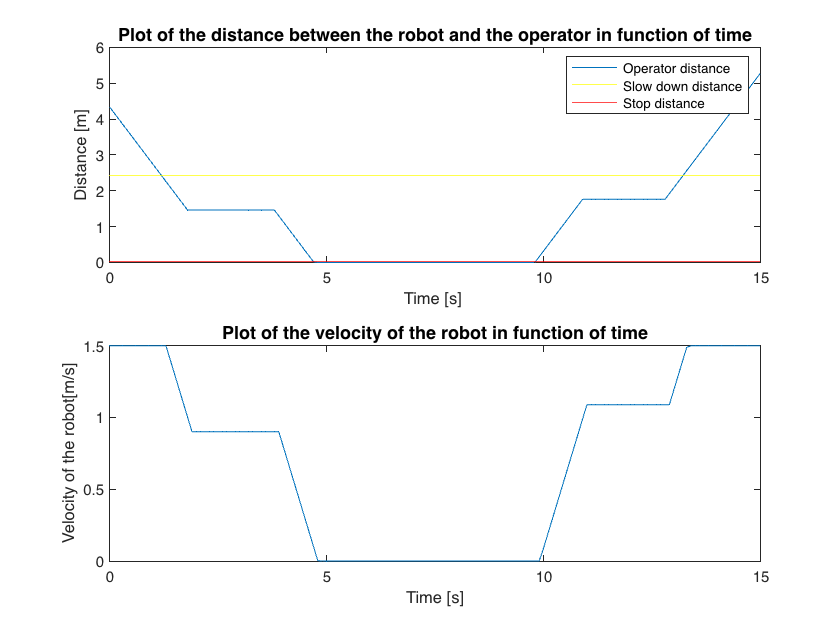

    %We simulate the movement of an operator (We want to see if the robot
    %has a good behavior depending of the distance)
    %We take into account the speed at which the human is approaching and we multiply by an iteration of time (0.1s) to get the distance traveled
    if (i<20) 
    Total_Distance = Total_Distance - 0.1 * v_human; %Approaching the robot with constant velocity
    end 

    if (i >=20) && (i<40)
    Total_Distance = Total_Distance;   %The operator doesn't move
    end

    if (i >=40) && (i<80)
    Total_Distance = Total_Distance - 0.1 * v_human; %Approaching the robot with constant velocity
    end 

    if (i >=80) && (i<100) 
    Total_Distance = Total_Distance;   %The operator doesn't move
    end 

    if (i >=100) && (i<=110)
    Total_Distance = Total_Distance + 0.1 * v_human;  %Walking away from the robot with constant velocity
    end 

    if (i >=110) && (i<130)
    Total_Distance = Total_Distance;     %The operator doesn't move
    end 


    if (i >=130)
    Total_Distance = Total_Distance + 0.1 * v_human;  %Walking away from the robot with constant velocity
    end 
    

The distance when the robot will start to slow down : 2.4174 m


    if (Total_Distance < 0)
    Total_Distance =0;       %Avoid negative value
    end
    Distance(i)= Total_Distance;

The distance when the robot has to stop : 0.018 m


    i=i+1;

end 

We finally plot the graph of the distance between the robot and the operator and the robot's velocity in the time function.

t = 0:0.1:15;  %Time

%Plot the 2 figures of the distance between the robot and the operator and
%the velocity of the robot in function of time

subplot(211)
plot(t,Distance,'DisplayName','Operator distance')
hold on
yline(Sc,'y','DisplayName','Slow down distance')
hold on
yline(D_Stop,'r','DisplayName','Stop distance')
lgd = legend;
xlabel('Time [s] ')
ylabel('Distance [m]')
title('Plot of the distance between the robot and the operator in function of time','FontSize',12)
hold off


subplot(212)
plot(t,Velocity)
xlabel('Time [s]')
ylabel('Velocity of the robot[m/s]')
title('Plot of the velocity of the robot in function of time','FontSize',12)
hold off

X = ['The distance when the robot will start to slow down : ',num2str(Sc),' m'];

disp(X)

X = ['The distance when the robot has to stop : ',num2str(D_Stop),' m'];

disp(X)



**Disclaimer:** The algorithm is based on TS/ISO15066 and can be used to estimate and simulate the speed and separation monitoring behaviour. Please only use this script in a research context and consult a certified integrator to implement speed and separation monitoring in the industry.

#### ***Sources: ***

 [1] Tom M. Speed and Separation Monitoring for Robotic Applications. April 2022. Link : [https://perma.cc/NQ4T-Q63R](https://perma.cc/NQ4T-Q63R) 

[2] Paul Glogowski, Alexander Bohmer, Alfred Hypki and  Bernd Kuhlenkotter. Robot Speed Adaption in Multiple Trajectory Planning and Integration in a Simulation Tool for Human-Robot Interaction. April 2021. Link : [https://perma.cc/S7VM-6FH9](https://perma.cc/S7VM-6FH9) 

[3] Marek Vagas and Alena Galajdova. APPLICATION OF SPEED AND SEPARATION MONITORING TECHNIQUE AT AUTOMATED ASSEMBLY PROCESS. June 2021. DOI: *10.17973/MMSJ.2021_6_2021036*

[4]  Urban B. Himmelsbach, Thomas M. Wendt, Nikolai Hangst, Philipp Gawron and Lukas Stiglmeier. Human–Machine Differentiation in Speed and Separation Monitoring for Improved Efficiency in Human–Robot Collaboration. October 2021. DOI: [10.3390/s21217144](http://dx.doi.org/10.3390/s21217144)

[5] Jeremy A. Marvel and Rick Norcross. Implementing speed and separation monitoring in collaborative robot workcells. April 2017. DOI: [https://doi.org/10.1016/j.rcim.2016.08.001](https://doi.org/10.1016/j.rcim.2016.08.001)

[6] TDK. Ultra-low Power Integrated Ultrasonic Time-of-Flight Range Sensor (CH101 datasheet). Link : [https://perma.cc/JV4A-EGK4](https://perma.cc/JV4A-EGK4) 

*[7] *Universal Robots. UR10e - user manual. Link: [https://perma.cc/4T8B-J9SE](https://perma.cc/4T8B-J9SE) 